## Introduction

A testbed was developed to spectrally reproduce display stimuli for testing color calibration kits. The testbed, LightSim, consists of a tunable light source (TLS) for generating the target spectrum, an integrating sphere for diffusing the light for the color calibration sensor, computer hardware and software components for controlling the TLS, and a spectroradiometer for measuring the output spectrum. 

The testbed was treated as a 1-pixel, 1024-primary, 40,000-level display in contrast to the regular n-pixel, 3-primary, 256-level displays. The TLS used 1024 columns of a digital light processor (DLP) to selectively reflect the dispersed light coming from a xenon lamp after passing the grating. Each column was independently controlled by an integer value between 0 and 40,000 to form a bandpass filter with a bandwidth of 25 nm at a spectral resolution of 0.40 nm. The spectroradiometer measured the output spectrum between 380 nm and 780 nm at 1 nm resolution.

The final forward model accepts a vector of 1024 column values and predicts the output spectrum of 401 wavelengths.

To simulate the stimuli of a given display, the TLS model needed to be inversed by solving the 1024x401 matrix equation with the R General Purpose Optimization tool (optim L-BFGS-B). The inverse model accepts a target spectrum and then calculates the 1024 column values.

## Setup

Controlling OL490/HIMS1 and PR730 in WO62/3143


[ret hname] = system('hostname');
if isequal(hname(1:end-1),'wcc-FX')
    HIMS = 1;
else
    HIMS = 2;
end
HIMS

HIMS = 1


ol

ol =   OL490Class with properties:

                   m: [1×1 OL490_SDK_Dll.OL490SdkLibrary]
            asmCyUSB: []
        asmOLIPlugin: []
         asmOL490Lib: []
         asmOL490SDK: []
    max_column_value: 40000
           gamma_lut: [11×2 double]
           classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Class'
               vec_x: []
               vec_y: []
               vec_z: []
                HIMS: 1


cs

cs =   pr730Class with properties:

          ver: '6/15/2022'
      comPort: [1×1 rs232Class]
    connected: 1
     settings: '00000,FP-730-4,None,None,None,2 deg,Metric,Adaptive,500 msec,Normal,1 cycles,2 deg,No Smart Dark,Standard Sensitivity,No Sync,20.00 Hz,5 nm'


ols = OL490Sim(HIMS)

ols =   OL490Sim with properties:

             col_spec: []
             HIMS_VER: 'HIMS1_07032022'
       spike_filename: 'spike_HIMS1_07032022.mat'
       gamma_filename: 'gamma_HIMS1_07032022.mat'
    col_spec_filename: 'col_spec_HIMS1_07032022.mat'
             speC_max: []
             speC_min: []
            reflC_min: []
            classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Sim'
        spikedatapath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Sim/spike_HIMS1_07032022.mat'
     col_specdatapath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Sim/col_spec_HIMS1_07032022.mat'
        gammadatapath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Sim/gamma_HIMS1_07032022.mat'



CHARACTERIZING = 0

CHARACTERIZING = 0

ans = 'Set the light to green and show its spectrum'

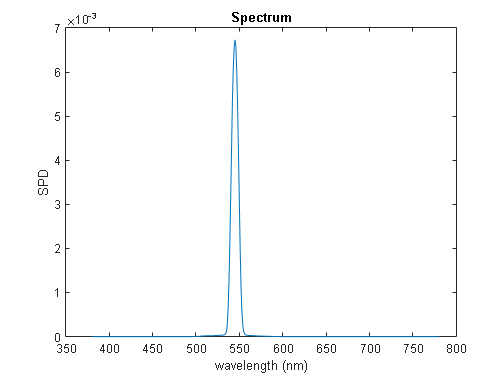


clf; ols.check_ol_cs(ol,cs)

## Collect gamma measurement data

Measure 0%, 10%,... 100% of the fully on output spectrum.

Use the area under the curve (i.e., total power, which should be proportional to luminance) to determine gamma.

In the characterization stage, 350 out of 1024 columns were measured to construct the look-up table of the spectral reflectance. To avoid the prolonged measurement time required by the spectroradiometer to collect a limited number of photons reflected by one column only, seven columns were activated simultaneously to generate eight spikes that were at least 50 nm apart without any cross-talking.

if CHARACTERIZING
    ols.FWD_stimulate_gamma (ol,cs)
end

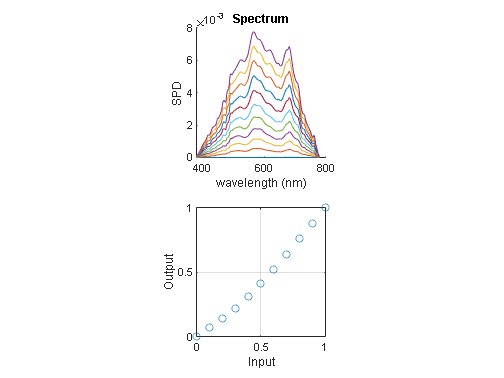

ols.FWD_stimulate_gamma_finding

## Collect spectral measurement data

if CHARACTERIZING
    ols.FWD_stimulate_spectrally (ol,cs)
end

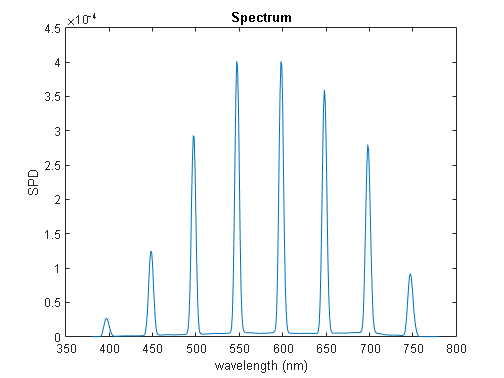

ols.FWD_stimulate_spectrally_finding

## Analyze spectral measurement data

ols.FWD_characterize_spectrally

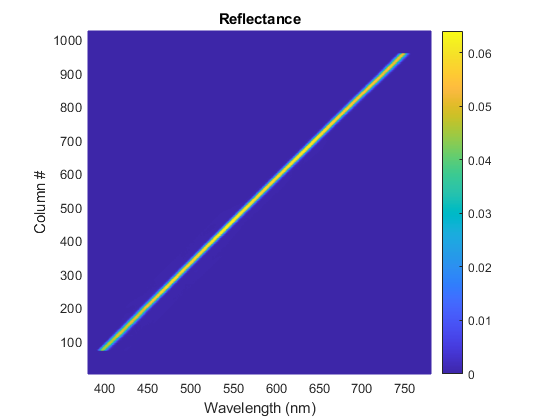

ols.FWD_characterize_spectrally_finding

## Check accuracy of the forward model

Column 1000 is not modeled because 780 nm is excluded in the combs.

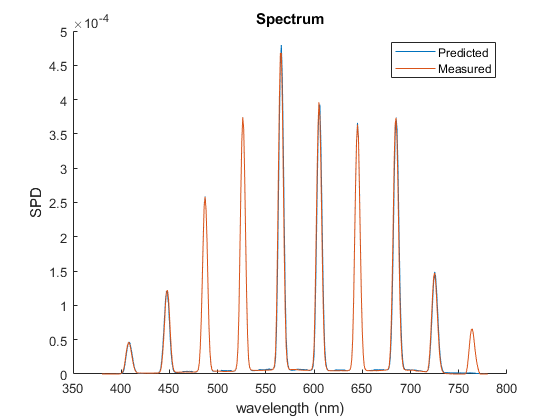

col_range  = [100:100:1000];

vec = OL490Class.VEC_multiple_peaks(col_range);

refl = ols.FWD_vec2reflC(vec);
spec = ols.FWD_vec2spdC(vec);

clf
hold on
spec.plot

mea = ol.setColumn1024GammaandMeasure(vec,cs);
mea.plot

legend('Predicted','Measured')

## Check accuracy of the inverse model with 3 displays

Spectra of the red, green, and blue primaries of three displays were used to represent different color gamuts and lighting methods. A virtual reality device based on OLED (Oculus Rift), a professional-grade display based on CCFL-backlighting (NEC PA271), and a consumer-grade display based on LED-backlighting (HP Z24X) were measured to represent the DCI-P3, AdobeRGB, and sRGB color spaces. For each display, a model was created to accept the RGB input values and then predict the output spectrum.

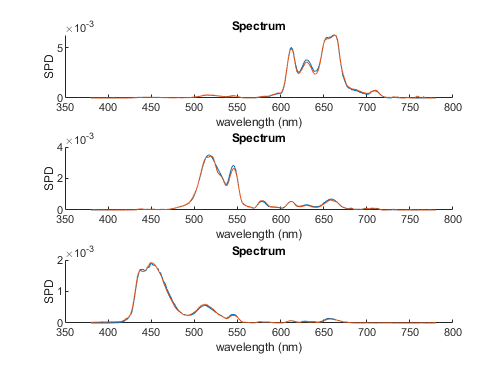

### NEC

disp_nec = NECPA271Sim(HIMS)

obj =   NECPA271Sim with properties:

            sc: 0.5000
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS1.mat'


disp_nec =   NECPA271Sim with properties:

            sc: 0.5000
        spec_r: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1.7776e-06 3.3536e-06 2.6448e-06 1.4197e-06 2.1417e-08 0 0 4.3892e-07 1.0145e-06 1.0251e-06 1.0195e-07 0 0 0 0 0 0 0 0 0 0 0 0 0 0 2.6946e-06 4.8578e-06 7.1572e-06 9.6743e-06 1.2673e-05 … ]
        spec_g: [0 0 0 0 0 0 0 0 0 0 0 0 1.0262e-06 1.7985e-06 1.9720e-06 1.7812e-06 1.3067e-06 5.6359e-07 0 0 0 0 0 0 5.6346e-07 1.2220e-06 1.3951e-06 1.2828e-06 8.5870e-07 0 0 0 0 0 0 0 2.9403e-07 1.9276e-06 2.2126e-06 2.1815e-06 1.9672e-06 … ]
        spec_b: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 3.6628e-07 1.5865e-06 3.6028e-06 5.8140e-06 8.0981e-06 9.8720e-06 1.0614e-05 1.1800e-05 1.3872e-05 1.7628e-05 2.3943e-05 3.1855e-05 4.1323e-05 5.1690e-05 6.1931e-05 7.4756e-05 … ]
     classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: []
        

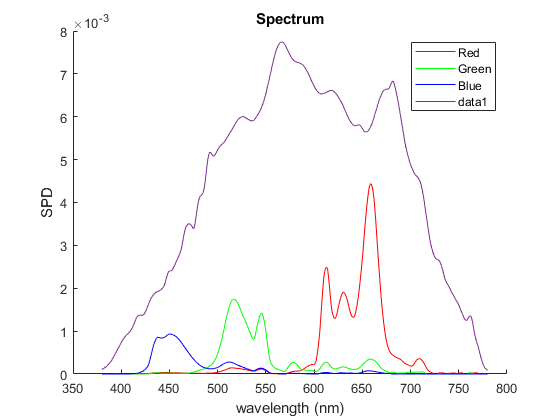

clf; check_RGB_primaries(ol,ols,cs,disp_nec)

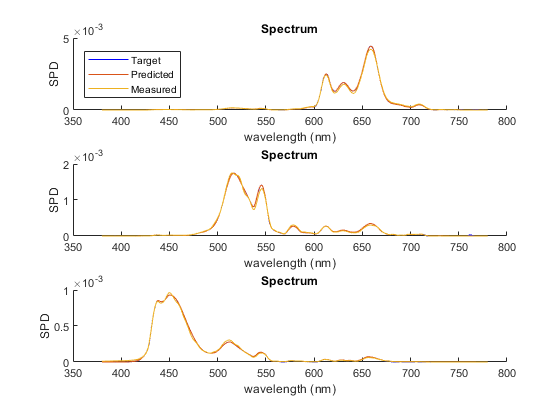

if CHARACTERIZING
    disp_nec.OL490_model(ols)
end
disp_nec.OL490_load_vec;

compare_RGB_primaries(ol,ols,cs,disp_nec)

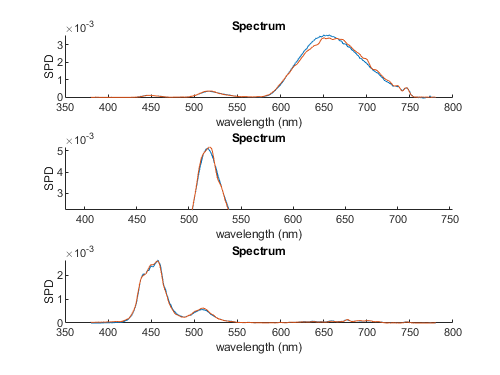

### HP

disp_hp = HPZ24xSim(HIMS)

obj =   HPZ24xSim with properties:

            sc: 0.5000
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS1.mat'


disp_hp =   HPZ24xSim with properties:

            sc: 0.5000
        spec_r: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1.2850e-06 3.9654e-06 3.8835e-06 3.0822e-06 1.9066e-06 1.1277e-06 1.2337e-06 1.4070e-06 1.5579e-06 1.3805e-06 6.6376e-07 0 0 0 1.0329e-06 2.4265e-06 3.5166e-06 3.4062e-06 1.0724e-06 0 0 0 0 0 … ]
        spec_g: [8.4358e-06 1.1185e-05 1.3537e-05 1.5261e-05 1.6076e-05 1.4495e-05 1.0683e-05 6.4796e-06 2.5121e-06 8.3028e-07 1.6905e-06 3.0008e-06 4.2564e-06 3.7746e-06 1.2235e-06 0 0 0 0 0 2.2264e-06 3.4603e-06 3.0196e-06 2.2312e-06 1.3321e-06 … ]
        spec_b: [0 0 0 0 0 0 1.3553e-06 3.3265e-06 5.0161e-06 5.3049e-06 4.0944e-06 2.6220e-06 1.2220e-06 8.7829e-07 1.8298e-06 3.0698e-06 4.3887e-06 5.3514e-06 5.7508e-06 5.8842e-06 5.7420e-06 4.9657e-06 3.4928e-06 2.1778e-06 1.3431e-06 2.1516e-06 … ]
     classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: []
         vec_r: []
     

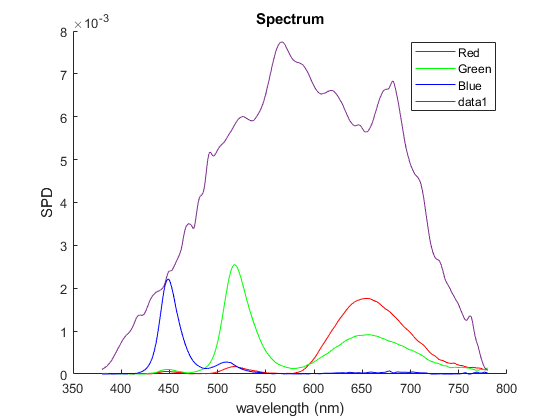

clf; check_RGB_primaries(ol,ols,cs,disp_hp)

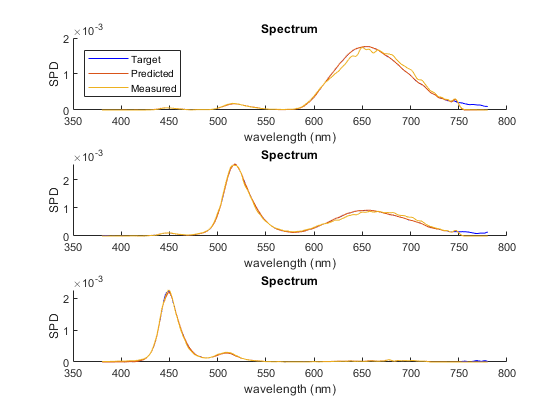

if CHARACTERIZING
    disp_hp.OL490_model(ols)
end
disp_hp.OL490_load_vec;

compare_RGB_primaries(ol,ols,cs,disp_hp)

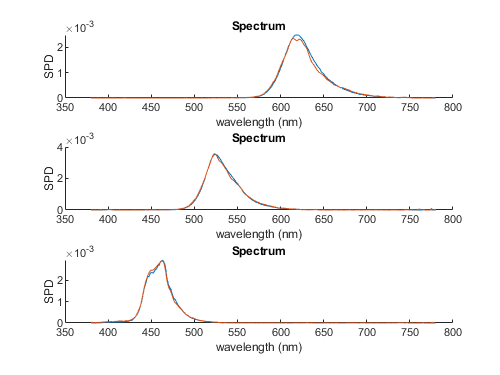

### Rift

disp_rift = RiftSim(HIMS)

obj =   RiftSim with properties:

      dataspec: []
        ramp_r: []
        ramp_g: []
        ramp_b: []
         lut_x: []
           lut: []
            sc: 0.5000
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@RiftSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS1.mat'


disp_rift =   RiftSim with properties:

      dataspec: [1024×401 double]
        ramp_r: [256×401 double]
        ramp_g: [256×401 double]
        ramp_b: [256×401 double]
         lut_x: [18×1 double]
           lut: [18×3 double]
            sc: 0.5000
        spec_r: [1.3350e-26 1.3120e-26 1.2895e-26 1.5235e-06 4.5915e-07 5.3700e-07 1.3730e-06 1.4820e-06 4.3015e-07 8.5450e-07 1.1380e-26 1.1230e-26 3.4960e-06 1.0790e-06 2.3215e-06 1.0495e-26 1.0310e-26 1.0090e-26 9.9000e-27 9.7350e-27 9.5450e-27 … ]
        spec_g: [2.3440e-06 8.7700e-06 2.6370e-06 5.2150e-07 2.7965e-06 4.1865e-06 2.2615e-06 6.4850e-06 1.1930e-06 1.9235e-26 1.8970e-26 1.8715e-26 1.8385e-26 1.8060e-26 5.0750e-07 3.8220e-07 2.5450e-07 4.4245e-06 2.8315e-06 4.2295e-06 1.6335e-05 … ]
        spec_b: [3.5625e-06 2.3105e-08 2.1495e-26 4.9065e-06 1.4790e-06 1.7295e-06 4.4215e-06 1.9895e-26 5.7400e-08 3.8595e-06 6.1550e-06 5.8000e-06 1.2140e-05 1.4555e-05 6.315

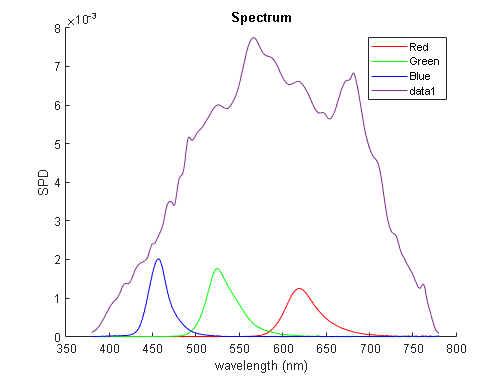

clf; check_RGB_primaries(ol,ols,cs,disp_rift)

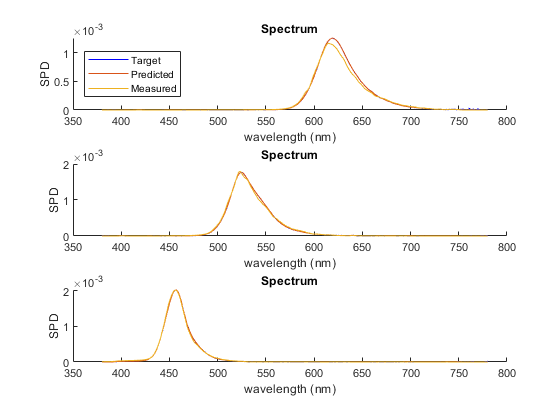


if CHARACTERIZING
    disp_rift.OL490_model(ols)
end
disp_rift.OL490_load_vec;
compare_RGB_primaries(ol,ols,cs,disp_rift)

## ColorChecker Experiments

In the experiment, a color calibration sensor (DataColor Spyder X Elite) was tested with the 24 patches following the ColorChecker design. Each spectrum was simultaneously measured by the spectroradiometer (Konica-Minolta CS2000a) as the ground truth. The subject sensor allowed the user to select one of four backlighting modes (“White LED”, “Standard LED”, “General”, and “GB LED”) for improving the estimation. The test results were evaluated using the CIEDE2000 color difference metric. The experiment results show adequate linearity of luminance responses in the mid-range. Most color differences were less than 2.5 ΔE00, except for the darkest patch #24, indicating the limited capability of measuring dark shades. None of the four backlighting modes outperformed the others, and two blue patches #8 and #13 generated the most diverse results. This exercise demonstrated the utility of the LightSim for emulating arbitrary spectra without employing actual displays based on different backlighting methods.

return

Try CIE D65

d65 = SpectrumClass.CIE_D(5000);
target_orig = d65.amplitude;

sc = 0.00002;
clf
hold on
ols.speC_max.plot
plot(380:780,target_orig*sc)

target = target_orig * sc;
vec = ols.INV_spd2vec(target);
vec_d50 = vec;

mea = ol.setColumn1024GammaandMeasure(vec,cs);
clf
hold on
plot(380:780,target)
mea.plot
mea.xyz

function check_RGB_primaries (ol,ols,cs,disp)
disp.show_spectra;
ols.speC_max.plot
end

function compare_RGB_primaries (ol,ols,cs,disp)

clf

subplot(3,1,1)
hold on
v = disp.vec_r;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_r,'b')
s_predicted.plot
mea.plot
legend('Target','Predicted','Measured')
legend('Location','west')

subplot(3,1,2)
hold on
v = disp.vec_g;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_g,'b')
s_predicted.plot
mea.plot

subplot(3,1,3)
hold on
v = disp.vec_b;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_b,'b')
s_predicted.plot
mea.plot

end